# Historical Value-at-Risk Forecasting

## Exercise 72

In this script, we will use historical simulations, which simply use the empirical CDF, to forecast VaR. We will do this analysis for both the SP500 and the EUR/USD rate.

### Loading the data and selecting series

Let's begin by loading the data:

clear all
clc
% Downloading the SP500 data: 
fred_sp500 = fetch(fred(), 'SP500')

fred_sp500 = struct with fields:
                 Title: ' S&P 500'
              SeriesID: ' SP500'
                Source: ' S&P Dow Jones Indices LLC'
               Release: ' Standard & Poors (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily, Close'
                 Units: ' Index'
             DateRange: ' 2010-02-26 to 2020-02-25'
           LastUpdated: ' 2020-02-25 7:10 PM CST'
                 Notes: ' The observations for the S&P 500 represent the daily index value at market close.  The Federal Reserve Bank of St. Louis and S&P Dow Jones Indices LLC have reached a new agreement on the use of Standard & Poors and Dow Jones Averages series in FRED. FRED and its associated services will include 10 years of daily history for Standard & Poors and Dow Jones Averages series.  The S&P 500 is regarded as a gauge of the large cap U.S. equities market. The index includes 500 leading companies in leading industries of the U.S. econ

% Downloading the EUR/USD data:
fred_euro = fetch(fred(), 'DEXUSEU')

fred_euro = struct with fields:
                 Title: ' U.S. / Euro Foreign Exchange Rate'
              SeriesID: ' DEXUSEU'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.10 Foreign Exchange Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Daily'
                 Units: ' U.S. Dollars to One Euro'
             DateRange: ' 1999-01-04 to 2020-02-21'
           LastUpdated: ' 2020-02-24 3:49 PM CST'
                 Notes: ' Noon buying rates in New York City for cable transfers payable in foreign currencies.'
                  Data: [5515×2 double]


% Let's first get rid of the NaN values
fred_sp500.Data = fred_sp500.Data(~isnan(fred_sp500.Data(:,2)),:);
fred_euro.Data = fred_euro.Data(~isnan(fred_euro.Data(:,2)),:);
% Getting the vector with the relevant dates:
dates_sp = fred_sp500.Data(:,1);
dates_euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1),1);
% Finally, getting sp500 and euro data for the last 10yrs:
sp500 = fred_sp500.Data(:,2);
euro = fred_euro.Data(fred_euro.Data(:,1)>=dates_sp(1), 2);

Now select the returns of which series we want to analyse:

% Selecting SP500:
r = diff(log(sp500))*100;
dates = dates_sp(2:end); 
% Selecting EUR/USD:
%r = diff(log(euro))*100;
%dates = dates_euro(2:end); 

### VaR Forecasting

The HS VaR is simply the unconditional quantile at any point in time. We will compute this using the MATLAB function `quantile`. 

help quantile

 quantile Quantiles of a sample.
    Y = quantile(X,P) returns quantiles of the values in X.  P is a scalar
    or a vector of cumulative probability values.  When X is a vector, Y is
    the same size as P, and Y(i) contains the P(i)-th quantile.  When X is
    a matrix, the i-th row of Y contains the P(i)-th quantiles of each
    column of X.  For N-D arrays, quantile operates along the first
    non-singleton dimension.
 
    Y = quantile(X,P,'all') calculates quantiles of all the elements in X.
    The smallest dimension of Y has length LENGTH(P)
 
    Y = quantile(X,P,DIM) calculates quantiles along dimension DIM.  The
    DIM'th dimension of Y has length LENGTH(P).
 
    Y = quantile(X,P,VECDIM) calculates quantiles of elements of X based
    on the dimensions specified in the vector VECDIM. The smallest dimension
    specified in VECDIM has length LENGTH(P).
 
    Y = qu

We will use this `quantile` function to estimate the quantiles using the data from $t_0$ up to $t-1$. Therefore, we will do this for $t\ge 0\ldotp 25\;T$such that we have enough data points to estimate the quantiles. Let's do it!

% Creating the HS vectors:
T = length(r);
HS_forecast_05 = nan(T,1);
HS_forecast_01 = nan(T,1);
% Iterate through the time series.  The forecast for t+1 is stored in t:
for t = ceil(T*0.25):T
    HS_forecast_05(t) = quantile(r(1:(t-1)),0.05);
    HS_forecast_01(t) = quantile(r(1:(t-1)),0.01);
end
HS_VaR = [HS_forecast_05 HS_forecast_01];

### Plotting

We will now plot the returns, the HS VaR and the HITs. The non-HITs are removed from the graph by setting their values to NaN. 

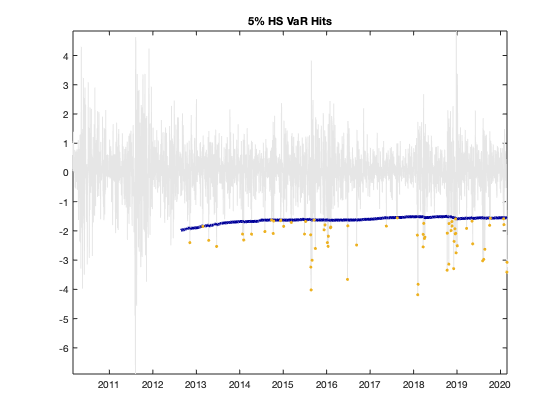

% 5% VaR
figure()
% Checking when r < HS_forcast:
hit05 = r(2:end)<HS_forecast_05(1:end-1);
% Getting returns for these days:
scaled_hit = hit05.*r(2:end);
% Setting non-HITs to NaN:
scaled_hit(~hit05) = nan;
% Plotting:
h = plot(dates,r,dates,HS_forecast_05,dates(2:end),scaled_hit);
set(h(1),'Color',[.9 .9 .9])
set(h(2),'Color',[.0 0 .6],'LineWidth',3)
set(h(3),'LineStyle','none','Marker','.')
title('5% HS VaR Hits')
axis tight
datetick('x','keeplimits')

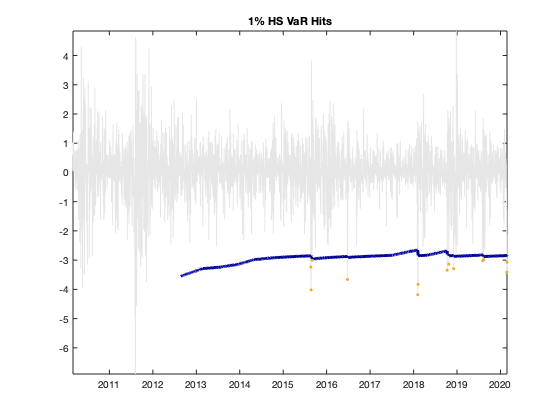

% 1% VaR
figure()
% Checking when r < HS_forcast:
hit01 = r(2:end)<HS_forecast_01(1:end-1);
% Getting returns for these days:
scaled_hit = hit01.*r(2:end);
% Setting non-HITs to NaN:
scaled_hit(~hit01) = nan;
% Plotting:
h = plot(dates,r,dates,HS_forecast_01,dates(2:end),scaled_hit);
set(h(1),'Color',[.9 .9 .9])
set(h(2),'Color',[0 0 .6],'LineWidth',3)
set(h(3),'LineStyle','none','Marker','.')
axis tight
title('1% HS VaR Hits')
datetick('x','keeplimits')

Although not a formal test, these plots do a very good job in presenting the results from our historical VaR forecasts. By doing the plots for both the SP&500 and the EUR/USD exchange rate, we see that realized return is lower than the forecasted VaR more often in the EUR/USD. This is likely because equity returns are more spread than exchange rate returns for developed markets. As a result, the fat tailedness (that we already saw in the density plots in previous classes) shows up more clearly in the EUR/USD plot.

To conclude, let's save the dataset with the VaR forecasts:

save HS_VaR HS_VaR